# 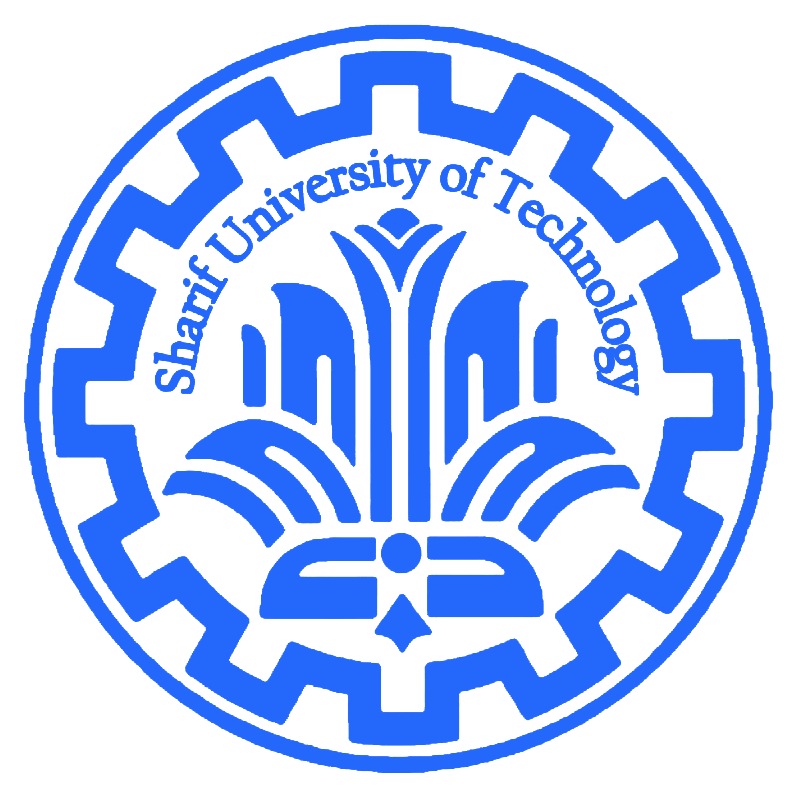

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#2
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#2}$$


**............................................................................................................**

### 
$$\text{Part A}.$$
 

.............................................................................................................

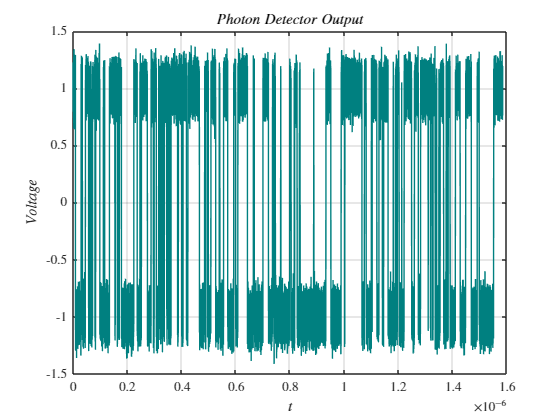

data = readtable("Q2_DATA.csv");

points = data.Var1;
voltage = data.Var2;
plot(points,voltage,'Color','#008080')
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Photon\;Detector\;Output$','interpreter','latex')
xlabel('$t$','interpreter','latex')
ylabel('$Voltage$','interpreter','latex')
grid on;

prev_point = points(1);
pulse_length = zeros(1,1);

k = 1;
for i = 2:length(points)
    if(voltage(i)*voltage(i-1) < 0)
        pulse_length(k) = points(i-1) - prev_point;
        prev_point = points(i);
        k = k + 1;
    end
end
lambda = mean(pulse_length)^(-1);
fprintf('The estimated value of \x03bb : %g', lambda)

The estimated value of λ : 9.30171e+07

### 
$$\text{Part C}.$$
 

.............................................................................................................

t = 16.67e-9;
I = zeros(1,1);
last_endpoint = 0;

i = 0;
integral = zeros(1,1);
while last_endpoint + t <= points(end)
    points_t = points(last_endpoint <= points & points <= (last_endpoint + t)); % time slices
    voltage_t = voltage(last_endpoint <= points & points <= (last_endpoint + t));

    areas = diff(points_t) .* voltage_t(1:end-1); % integration
    I(i+1,1)  = sum(areas)/t;
    i = i + 1;
    
    next_points = points(points > (last_endpoint + t));
    next_voltages = voltage(points > (last_endpoint + t));

    idx = find(next_voltages > 0 , 1); % Find the beginning of next pulse
    last_endpoint = next_points(idx);
end

eta_I = mean(I);
lambda_estimate = fzero( @(lambda) (1 - exp(-2*lambda*t)) / (2*lambda*t) - eta_I, 1e8);
fprintf('The estimated value of \x03bb : %g', lambda_estimate)

The estimated value of λ : 1.00917e+08